## Analysis Script

Processes data to generate statistical measures for both static and non static scenarios

### Initialization steps.

clc;    % Clear the command window.
close all;  % Close all figures (except those of imtool.)
clear;  % Erase all existing variables. Or clearvars if you want.

workspace;  % Make sure the workspace panel is showing.
format long g;
format compact;
fontSize = 20;



### **Static Data Processing**

clear all
load("../data/MAT/DataFinal.mat")
% clear bSel fontSize i nonstatic_file nonStaticbag path static_bag static_file 
clearvars -except ALT_static UTMN_static2 UTME_static2 LATStatic LONGStatic


RefUTME = 797.00 %325797 stripped to 797

RefUTME =    797

RefUTMN = 653.00 %4687653  stripped to 653

RefUTMN =    653



meanLAT   = mean(LATStatic)

meanLAT =           42.3216296367816

meanLON   = mean(LONGStatic)

meanLON =          -71.1139725724138

meanUTME  = mean(UTME_static2)

meanUTME =           806.443084545908

meanUTMN  = mean(UTMN_static2)

meanUTMN =           651.542146572212

meanALT   = mean(ALT_static)

meanALT =           41.2470344827586


stdevLAT  = std(LATStatic)

stdevLAT =       1.03197734678712e-05

stdevLON  = std(LONGStatic)

stdevLON =       4.14338746199675e-05

stdevUTME = std(UTME_static2)

stdevUTME =           3.38786920511866

stdevUTMN = std(UTMN_static2)

stdevUTMN =           1.22525157310543

stdevALT  = std(ALT_static)

stdevALT =           3.87866492596683




varLAT  = var(LATStatic)

varLAT =       1.06497724428178e-10

varLON  = var(LONGStatic)

varLON =       1.71676596602318e-09

varUTME = var(UTME_static2)

varUTME =           11.4776577509914

varUTMN = var(UTMN_static2)

varUTMN =           1.50124141739734

varALT  = var(ALT_static)

varALT =           15.0440416079253



L2Norm_error = norm([meanUTME,meanUTMN]-[RefUTME, RefUTMN])
static_norm_error_vec=[]
for i=1:size(UTMN_static2)
    static_norm_error_vec(i)=norm([RefUTME,RefUTME]-[UTME_static2(i),UTMN_static2(i)]);
end

static_rms_eror = sqrt(mean(static_norm_error_vec.^2))


L2Norm_error =             9.554955905606

static_norm_error_vec =
     []


static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

static_norm_error_vec =           96.3321351095088

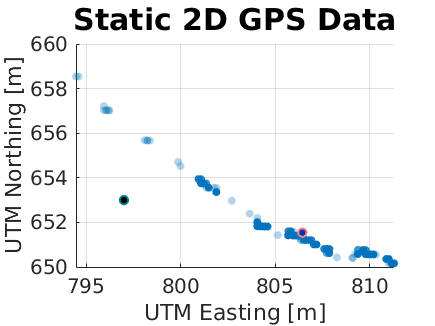



open("../data/Fig/StaticUTMPlot_2D_Truncated.fig")
hold on
scatter(RefUTME,RefUTMN,40,'MarkerEdgeColor',[0 .5 .5],...
'MarkerFaceColor',[0 0 0],...
'LineWidth',1.5)

scatter(meanUTME,meanUTMN,40,'MarkerEdgeColor',[1 .5 .5],...
'MarkerFaceColor',[0 .2 .7],...
'LineWidth',1.5)


savefig("Analysis_2d_static.fig")
save("Static_analysis.mat")

### Motion Data

clear all
load("../data/MAT/DataFinal.mat")
% clear bSel fontSize i nonstatic_file nonStaticbag path static_bag static_file 
clearvars -except ALT_motion UTMN_motion2 UTME_motion2 LATMotion LONGMotion

[best_fit_Coeffs,Structure] = polyfit(UTME_motion2,UTMN_motion2, 1);
UTMEFit =linspace(min(UTME_motion2), max(UTME_motion2), 4*size(UTME_motion2,1))

UTMEFit =           596.887367404997          597.176248269709          597.465129134421          597.754009999133          598.042890863845          598.331771728557          598.620652593269          598.909533457981          599.198414322692          599.487295187404          599.776176052116          600.065056916828           600.35393778154          600.642818646252          600.931699510964          601.220580375676          601.509461240387          601.798342105099          602.087222969811          602.376103834523          602.664984699235          602.953865563947          603.242746428659          603.531627293371          603.820508158082          604.109389022794          604.398269887506          604.687150752218           604.97603161693          605.264912481642          605.553793346354          605.842674211066          606.131555075778          606.420435940489          606.709316805201          606.998197669913          607.287078534625          607.575959399337  

UTMNFit =linspace(min(UTMN_motion2), max(UTMN_motion2), 4*size(UTME_motion2,1)) 

UTMNFit =           571.978955104016           572.04687716661          572.114799229205          572.182721291799          572.250643354394          572.318565416989          572.386487479583          572.454409542178          572.522331604772          572.590253667367          572.658175729962          572.726097792556          572.794019855151          572.861941917745           572.92986398034          572.997786042934          573.065708105529          573.133630168124          573.201552230718          573.269474293313          573.337396355907          573.405318418502          573.473240481096          573.541162543691          573.609084606286           573.67700666888          573.744928731475          573.812850794069          573.880772856664          573.948694919259          574.016616981853          574.084539044448          574.152461107042          574.220383169637          574.288305232231          574.356227294826          574.424149357421          574.492071420015  

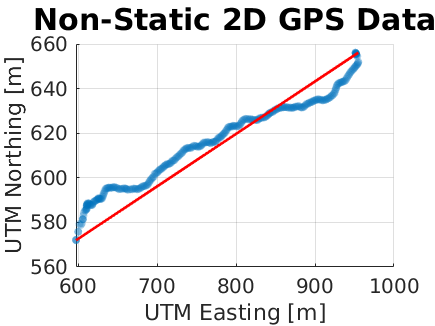

open("../data/Fig/NonStaticUTMPlot_2D_Truncated.fig")
hold on
plot(UTMEFit,UTMNFit,'r-', 'LineWidth',2)





Error_mat=[UTMEFit', UTMNFit']

Error_mat =           596.887367404997          571.978955104016
          597.176248269709           572.04687716661
          597.465129134421          572.114799229205
          597.754009999133          572.182721291799
          598.042890863845          572.250643354394
          598.331771728557          572.318565416989
          598.620652593269          572.386487479583
          598.909533457981          572.454409542178
          599.198414322692          572.522331604772
          599.487295187404          572.590253667367



UTM_error_vec=[];

for i=1:size(UTME_motion2,1)
     min = 1000;
    for j=1:size(Error_mat,1)
        if norm([UTME_motion2(i),UTMN_motion2(i)]-Error_mat(j,:))<min
            min = norm([UTME_motion2(i),UTMN_motion2(i)]-Error_mat(j,:));
        end
        
    end
    UTM_error_vec=[UTM_error_vec;min] %#ok<*AGROW> 
end

UTM_error_vec =      0

UTM_error_vec =                          0
          0.18580666877236


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec =                          0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 49×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 50×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 51×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 52×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 53×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 54×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 55×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 56×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 57×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 58×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 59×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 60×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 61×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 62×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 63×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 64×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 65×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 66×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 67×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 68×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 69×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 70×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 71×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 72×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 73×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 74×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 75×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 76×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 77×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 78×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 79×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 80×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 81×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 82×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 83×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 84×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 85×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 86×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 87×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 88×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 89×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 90×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 91×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 92×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 93×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 94×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 95×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 96×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 97×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 98×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 99×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 100×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 101×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 102×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 103×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 104×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 105×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 106×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 107×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 108×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 109×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 110×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 111×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 112×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 113×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 114×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 115×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 116×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 117×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 118×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 119×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 120×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 121×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 122×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 123×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 124×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 125×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 126×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 127×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 128×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 129×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 130×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 131×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 132×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 133×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 134×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 135×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 136×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 137×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 138×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 139×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 140×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 141×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 142×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 143×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 144×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 145×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 146×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 147×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 148×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 149×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 150×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 151×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 152×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 153×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 154×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 155×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 156×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 157×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 158×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 159×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 160×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 161×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 162×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 163×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 164×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 165×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 166×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 167×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 168×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 169×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 170×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 171×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 172×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 173×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 174×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 175×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 176×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 177×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 178×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 179×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 180×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 181×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 182×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 183×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 184×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 185×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 186×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 187×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 188×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 189×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 190×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 191×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 192×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 193×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 194×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 195×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 196×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 197×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 198×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 199×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 200×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 201×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 202×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 203×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 204×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 205×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 206×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 207×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 208×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 209×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 210×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 211×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 212×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 213×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 214×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 215×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 216×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 217×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 218×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 219×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 220×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 221×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 222×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 223×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 224×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 225×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 226×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 227×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 228×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 229×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 230×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 231×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 232×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 233×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 234×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 235×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 236×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 237×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 238×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 239×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 240×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 241×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 242×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 243×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 244×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 245×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 246×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 247×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 248×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 249×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 250×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 251×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 252×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 253×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 254×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 255×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 256×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 257×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 258×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 259×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 260×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 261×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 262×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 263×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 264×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 265×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 266×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 267×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 268×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 269×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 270×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 271×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 272×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 273×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 274×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 275×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 276×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 277×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 278×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 279×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 280×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 281×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 282×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 283×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 284×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 285×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 286×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 287×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 288×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 289×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 290×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 291×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 292×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 293×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 294×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 295×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 296×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 297×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 298×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 299×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 300×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 301×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 302×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 303×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 304×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 305×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 306×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 307×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 308×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 309×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841


UTM_error_vec = 310×1
                         0
          0.18580666877236
         0.185127765994292
           3.0670122487346
           3.0670122487346
          6.12174965540486
          5.27715789187199
          5.71480530301911
          7.19429751432841
          7.19429751432841





clear min
mean_error = sum(UTM_error_vec)/size(UTM_error_vec,1)
nonstatic_rms_error  = sqrt(mean(UTM_error_vec.^2))

mean_error =           6.35561485676462